# Sensing System - revC

Changes since previous version:

- Packaged all of the sensing subsystem into the attacker class so that it can be used in the simulation

- When using complex sampling, the sampling rate doesn't have to be 2x times the highest frequency you want to measure. It can be equal to the highest frequency you want to measure

- defined a new chirp threshold in the chirp_tracking_params struct to make it easier to determine if a chirp has been seen before

To-Do's:

## Key parts of the Sensing Subystem

### Debugging Capability

For each debuger array, the format will be as follows:

- 1st column - number of frames computed at that point

- 2nd column - number of chirps computed at that point

- remainder of columns - data taken

## Generate a Spectogram

Steps to generate spectoram:

- reshape into 1us wide windows to sample frequency at (ex: 50 samples per 1us when sampling at 50 Msps)

- reduce the number of samples in the window to the desired size of fft (ex: 32 bits)

- window the sample signal

- perform fft

### Revised Linear Model Computation:

link to resourse used to compute linear model: [https://online.stat.psu.edu/stat462/node/132/](https://online.stat.psu.edu/stat462/node/132/) 

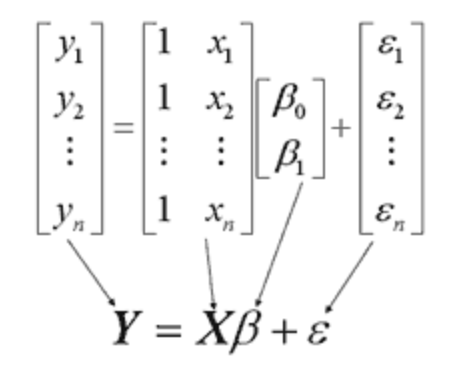

solving for this with out the Epsilon term though


$$\beta = (X^{T}X)^{-1}X^{T}Y$$


## Initializing the Sensing Subsystem in Simulink

clear;
simulator = Simulator_revA();

simulator.load_B210_victim_params;
simulator.load_B210_attacker_params;

%apply timing offsets as desired
simulator.Victim.timing_offset_us = 0;
simulator.Attacker.Subsystem_tracking.timing_offset_us = 0;

%configure the FMCW parameters
simulator.configure_FMCW_Radar_parameters();

%load default target, attacker, and victim positions and velocities
simulator.load_target_realistic;
simulator.load_realistic_attacker_and_victim_position_and_velocity();

%print out key parameters
simulator.Victim.print_chirp_parameters;

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.20 MHz/us
	 Idle Time: 			 1.95 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.49 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 1.54 MSps
	 Ramp End Time: 		 48.05 us
	 Chirp Tx Bandwidth: 		 57.66 MHz
	 Chirp Sampling Bandwidth: 	 49.87 MHz
	 ADC Sampling Period: 		 41.56 us
	 Chirp Cycle Time: 		 50.00 us
	 Chirp Wavelength: 		 3.89 mm



simulator.Victim.print_frame_parameters;

Frame Parameters
	 Number of Chirps 		 64
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.20 ms


%simulator.Victim.print_performance_specs;
simulator.Victim.print_FMCW_specs;

FMCW Specifications
	 FMCW sampling rate 		 58.52 MHz
	 Downsampling factor 		 38
	 Sweep time 			 48.05 us
	 Samples per chirp 		 2926.00 





%specify the number of frames to be computed
frames_to_compute = 5;

%initialize the sensing subsystem of the attacker
simulator.Attacker.Subsystem_spectrum_sensing.initialize_spectrum_sensing_parameters(simulator.Victim.FMCW_sampling_rate_Hz * 1e-6);

%initialize the sensing subsystem's debugger
simulator.Attacker.Subsystem_spectrum_sensing.initialize_debugger(1,simulator.Victim,frames_to_compute);


%for use in the simulink model
fft_size = simulator.Attacker.Subsystem_spectrum_sensing.spectogram_params.fft_size;
captured_chirps_buffer_size = simulator.Attacker.Subsystem_spectrum_sensing.chirp_tracking.captured_chirps_buffer_size;

%linear model computations in simulink
max_num_clusters = simulator.Attacker.Subsystem_spectrum_sensing.clustering_params.max_num_clusters;
threshold = simulator.Attacker.Subsystem_spectrum_sensing.clustering_params.min_num_points_per_cluster;
% half_fft_size = simulator.Attacker.Subsystem_spectrum_sensing.spectogram_params.fft_size/2;

## Rewritten Sensor Subsystem Code

simulator.initialize_sensing_subsystem_support()

while simulator.sensing_subsystem_support.frame_count < frames_to_compute
    received_signal = simulator.generate_sensing_subsystem_received_signal();

    %insert code here to simulate the transmission,propogation,and reception of the received signal

    simulator.Attacker.Subsystem_spectrum_sensing.process_received_signal(received_signal);
%     simulator.Attacker.Subsystem_spectrum_sensing.plot_received_spectogram()
end

%print out the relevant information
fprintf("Average Frame Duration: %5.3f us",simulator.Attacker.Subsystem_spectrum_sensing.frame_tracking.average_frame_duration);

Average Frame Duration: 33329.976 us

fprintf("Average Chirp Duration: %3.3f us",simulator.Attacker.Subsystem_spectrum_sensing.frame_tracking.average_chirp_duration);

Average Chirp Duration: 49.983 us

fprintf("Average Slope: %1.3f MHz/us",simulator.Attacker.Subsystem_spectrum_sensing.frame_tracking.average_slope);

Average Slope: 1.200 MHz/us

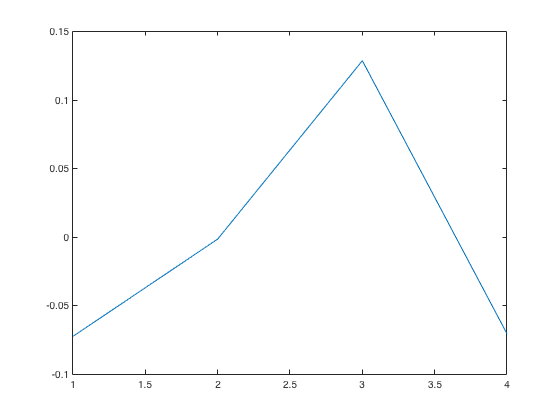

%compare the predicted frame start times with the actual frame start times
actual_frame_start_times = (2:frames_to_compute).' * simulator.Victim.FramePeriodicity_ms * 1e3 ... 
                                + simulator.Victim.IdleTime_us;
predicted_start_time_errors = simulator.Attacker.Subsystem_spectrum_sensing.frame_tracking.captured_frames(1:...
    simulator.Attacker.Subsystem_spectrum_sensing.frame_tracking.num_captured_frames,7) ...
                                - actual_frame_start_times;

clf;
plot(predicted_start_time_errors);

## Run the Debugger if enabled

if simulator.Attacker.Subsystem_spectrum_sensing.Debugger.enabled
    simulator.Attacker.Subsystem_spectrum_sensing.debugger_compute_errors(simulator.Victim);
    [summary_table] = simulator.Attacker.Subsystem_spectrum_sensing.debugger_summarize_errors();
    summary_table
end

summary_table = 4×3 table
                               Mean         Variance        MSE    
                            ___________    __________    __________

    Detected Times              0.06734      0.049354      0.053872
    Detected Frequencies      -0.080808       0.07107      0.077576
    Computed Slope          -0.00074277    3.7807e-05    3.8123e-05
    Computed Intercept         0.059583     0.0048228     0.0083428


## Check simulated values to make sure that they are the same as matlab computed values

### Initialize the Simulink model and run it

open_system('SensingSubsystem_revC');
stop_time = simulator.Attacker.Subsystem_spectrum_sensing.sampling_window_count *...
    simulator.Attacker.Subsystem_spectrum_sensing.spectogram_params.num_ADC_samples_per_spectogram /...
    simulator.Victim.FMCW_sampling_rate_Hz;
set_param('SensingSubsystem_revC','StopTime','stop_time');
warning_to_suppress_id = 'Coder:MATLAB:illConditionedMatrix';
warning('off',warning_to_suppress_id);
out = sim('SensingSubsystem_revC','SimulationMode','accelerator','SaveOutput','on');

### Reshaped Signal

%check a few chirps later to ensure that no timing errors or drift
reshaped_signal_simulink = out.reshaped_signal(:,:,2);
compare = all(simulator.Attacker.Subsystem_spectrum_sensing.reshaped_signal == reshaped_signal_simulink,'all');

if compare
    fprintf("Reshaped Signal: \t\t Matches")
else
    fprintf("Reshaped Signal: \t\t Does Not Match")
end

Reshaped Signal: 		 Matches

### Reshaped Signal - for fft

reshaped_signal_for_fft_simulink = out.reshaped_signal_for_fft(:,:,2);
compare = all(simulator.Attacker.Subsystem_spectrum_sensing.reshaped_signal_for_fft == reshaped_signal_for_fft_simulink,'all');

if compare
    fprintf("Reshaped Signal for fft: \t Matches")
else
    fprintf("Reshaped Signal for fft: \t Does Not Match")
end

Reshaped Signal for fft: 	 Matches

### Windowed Signal

windowed_signal_simulink = out.windowed_signal(:,:,2);
compare = all(simulator.Attacker.Subsystem_spectrum_sensing.windowed_signal == windowed_signal_simulink);
if compare
    fprintf("Windowed Signal: \t Matches")
else
    fprintf("Windowed Signal: \t Does Not Match")
end

Windowed Signal: 	 Matches

### Generated Spectogram

generated_spectogram_simulink = out.generated_spectogram(:,:,2);
compare = all(abs(simulator.Attacker.Subsystem_spectrum_sensing.generated_spectogram - generated_spectogram_simulink) <= 1e-10,'all');
if compare
    fprintf("Generated Spectogram: \t Matches")
else
    fprintf("Generated Spectogram: \t Does Not Match")
end

Generated Spectogram: 	 Matches

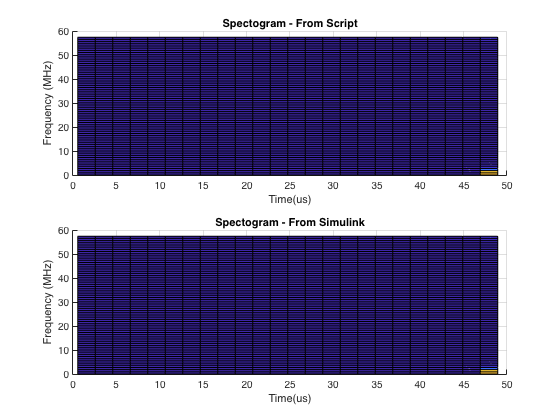

%imagesc(plot_params.times,plot_params.frequencies, abs(generated_spectogram));
clf;
subplot(2,1,1)
surf(simulator.Attacker.Subsystem_spectrum_sensing.plot_params.times,...
    simulator.Attacker.Subsystem_spectrum_sensing.plot_params.frequencies, ...
    abs(simulator.Attacker.Subsystem_spectrum_sensing.generated_spectogram));
title_str = sprintf('Spectogram - From Script');
title(title_str);
xlabel('Time(us)')
ylabel('Frequency (MHz)')
view([0,90.0])
subplot(2,1,2)
surf(simulator.Attacker.Subsystem_spectrum_sensing.plot_params.times,...
    simulator.Attacker.Subsystem_spectrum_sensing.plot_params.frequencies,...
    abs(generated_spectogram_simulink));
title_str = sprintf('Spectogram - From Simulink');
title(title_str);
xlabel('Time(us)')
ylabel('Frequency (MHz)')
view([0,90.0])

### Detect Peaks

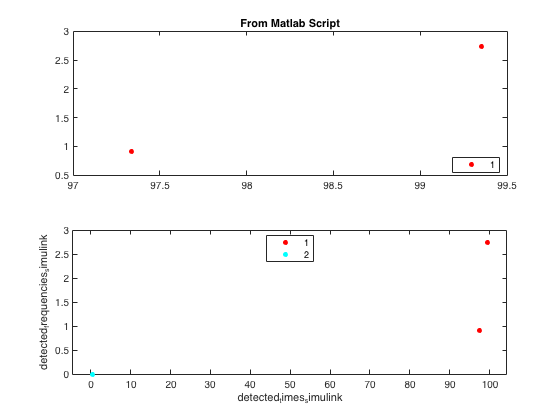

%obtain the detected times and frequencies
detected_times_simulink = out.detected_times(2,:);
detected_frequencies_simulink = out.detected_frequencies(2,:);
idx_simulink = out.idx(:,:,2);

clf;
subplot(2,1,1);
gscatter(simulator.Attacker.Subsystem_spectrum_sensing.detected_times,...
    simulator.Attacker.Subsystem_spectrum_sensing.detected_frequencies,...
    simulator.Attacker.Subsystem_spectrum_sensing.idx);
title('From Matlab Script')
subplot(2,1,2);
title('From Simulink')
gscatter(detected_times_simulink,detected_frequencies_simulink,idx_simulink);

%compare detected chirps and output
compare = all(detected_times_simulink(detected_frequencies_simulink > 0)...
    == simulator.Attacker.Subsystem_spectrum_sensing.detected_times); %frequencies won't be zero, time could be zero
if compare
    fprintf("Detected Times: \t Matches")
else
    fprintf("Detected Times: \t Does Not Match")
end

Detected Times: 	 Matches


compare = all(detected_frequencies_simulink(detected_frequencies_simulink > 0)...
    == simulator.Attacker.Subsystem_spectrum_sensing.detected_frequencies);
if compare
    fprintf("Detected Frequencies: \t Matches")
else
    fprintf("Detected Frequencies: \t Does Not Match")
end

Detected Frequencies: 	 Matches

### Verifing detected chirp observations

detected_chirps_simulink = out.detected_chirps(:,:,2);

compare = abs(detected_chirps_simulink(detected_chirps_simulink(:,2) ~=0, :)...
    - simulator.Attacker.Subsystem_spectrum_sensing.detected_chirps(...
    simulator.Attacker.Subsystem_spectrum_sensing.detected_chirps(:,2) ~=0, :)) ;
if isempty(compare) || compare < 1e-10 
    fprintf("Detected Chirps: \t Matches")
else
    fprintf("Detected Chirps: \t Does Not Match")
end

Detected Chirps: 	 Matches

### Verifing the computed slope and duration

captured_chirps_simulink = out.chirp_tracking_captured_chirps(:,:,2);
num_captured_chirps_simulink = out.chirp_tracking_chirp_count(2);
average_slope_simulink = out.chirp_tracking_slope(2);
average_chirp_duration_simulink = out.chirp_tracking_duration(2);

compare = all(abs(captured_chirps_simulink - simulator.Attacker.Subsystem_spectrum_sensing.chirp_tracking.captured_chirps) < 1e-10);
if compare
    fprintf("Captured Chirps: \t Matches")
else
    fprintf("Captured Chirps: \t Does Not Match")
end

Captured Chirps: 	 Matches

compare = (num_captured_chirps_simulink == simulator.Attacker.Subsystem_spectrum_sensing.chirp_tracking.num_captured_chirps);
if compare
    fprintf("Num Captured Chirps: \t Matches")
else
    fprintf("Num Captured Chirps: \t Does Not Match")
end

Num Captured Chirps: 	 Matches

compare = (abs(average_slope_simulink - simulator.Attacker.Subsystem_spectrum_sensing.chirp_tracking.average_slope) < 1e-10);
if compare
    fprintf("Average Slope: \t Matches")
else
    fprintf("Average Slope: \t Does Not Match")
end

Average Slope: 	 Matches


compare = (abs(average_chirp_duration_simulink - simulator.Attacker.Subsystem_spectrum_sensing.chirp_tracking.average_chirp_duration) < 1e-10);
if compare
    fprintf("Average Chirp Duration: \t Matches")
else
    fprintf("Average Chirp Duration: \t Does Not Match")
end

Average Chirp Duration: 	 Matches

### Verifing the computed frame information

frame_tracking_captured_frames_simulink = out.frame_tracking_frames(:,:,2);
frame_tracking_num_captured_frames_simulink = out.frame_tracking_frame_count(2);
frame_tracking_average_frame_duration_simulink = out.frame_tracking_frame_duration(2);
frame_tracking_average_chirp_duration_simulink = out.frame_tracking_chirp_duration(2);
frame_tracking_average_slope_simulink = out.frame_tracking_slope(2);

compare = all(abs(frame_tracking_captured_frames_simulink - simulator.Attacker.Subsystem_spectrum_sensing.frame_tracking.captured_frames) < 1e-10);
if compare
    fprintf("Captured Frames: \t Matches")
else
    fprintf("Captured Frames: \t Does Not Match")
end

Captured Frames: 	 Matches

compare = (frame_tracking_num_captured_frames_simulink == simulator.Attacker.Subsystem_spectrum_sensing.frame_tracking.num_captured_frames);
if compare
    fprintf("Num Captured Frames: \t Matches")
else
    fprintf("Num Captured Frames: \t Does Not Match")
end

Num Captured Frames: 	 Matches

compare = (abs(frame_tracking_average_frame_duration_simulink - simulator.Attacker.Subsystem_spectrum_sensing.frame_tracking.average_frame_duration) < 1e-10);
if compare
    fprintf("Average Frame Duration: \t Matches")
else
    fprintf("Average Frame Duration: \t Does Not Match")
end

Average Frame Duration: 	 Matches

compare = (abs(frame_tracking_average_chirp_duration_simulink - simulator.Attacker.Subsystem_spectrum_sensing.frame_tracking.average_chirp_duration) < 1e-10);
if compare
    fprintf("Average Chirp Duration (frame tracking): \t Matches")
else
    fprintf("Average Chirp Duration (frame tracking): \t Does Not Match")
end

Average Chirp Duration (frame tracking): 	 Matches

compare = (abs(frame_tracking_average_slope_simulink - simulator.Attacker.Subsystem_spectrum_sensing.frame_tracking.average_slope) < 1e-10);
if compare
    fprintf("Average Chirp Slope (frame tracking): \t Matches")
else
    fprintf("Average Chirp Slope (frame tracking): \t Does Not Match")
end

Average Chirp Slope (frame tracking): 	 Matches